# Breathing rate estimation 

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

Dependencies: files PEX_T1.mat, Free_T1.mat and Irregular_T1.mat. Code: br_rate_est.m, br_rate_est_freq.m, rescale1.m

**Acknowledgements:**

This notebook uses data from the database described in the paper: Shafiq, G., Veluvolu, K. Multimodal chest surface motion data for respiratory and cardiovascular monitoring applications. *Sci Data* **4, **170052 (2017). https://doi.org/10.1038/sdata.2017.52

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter9/Signal Quality'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

After the signal is extracted by a sensor, the first step is to  filter the signal using a band-pass filter in order to remove the  baseline as well as to remove cardiac frequency and other higher  frequency noise. Band-pass filter with the pass band of 0.08 Hz to 0.7  Hz (4.8 – 42 bpm) is used. After filtering, the signal is either  processed in time or frequency domain. Here, we will show only one  algorithm in each domain.

Time domain method is based on detection of the number of  local maxima and/or minima of a time waveform in a given time window.  In each time window, peaks and troughs are detected. The mean time difference between the peaks and between the through is  computed and the average of these two is used as a breathing rate. 

Fourier transform maximum selection is based on finding  the frequency  corresponding to the maximum peak in the frequency domain.

## Loading the signal

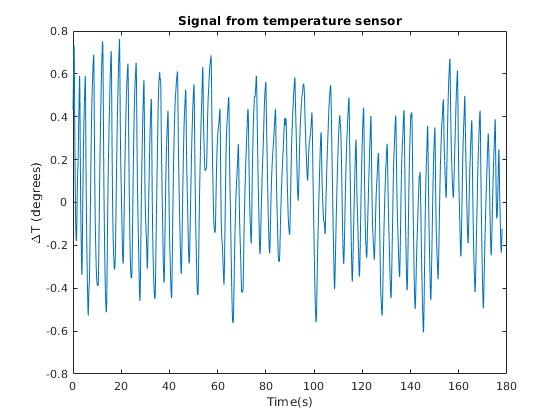

load('PEX_T1.mat')
%load('Irregular_T1.mat')
fs=100;
%load('Free_T1.mat')
t=1/fs:1/fs:length(mp36_s(1,:))/fs;resp_belt=mp36_s(4,:)';
resp_therm=mp36_s(4,:)';
resp_belt=mp36_s(2,:)';
figure
% subplot(211)
% plot(t,mp36_s(2,:))
% xlabel('Time(s)')
% ylabel('Amplitude(mV)')
% title('Signal from respiratory belt')

plot(t,resp_therm)
xlabel('Time(s)')
ylabel('\DeltaT (degrees)')
title('Signal from temperature sensor')

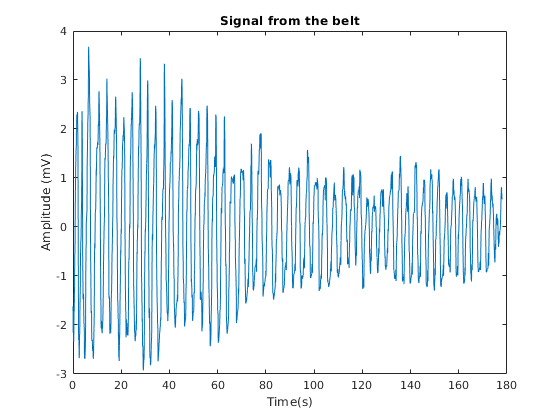

figure
plot(t,resp_belt)
xlabel('Time(s)')
ylabel('Amplitude (mV)')
title('Signal from the belt')

Segmenting the data into overlapping windows

Breathing_segment=15;
No_overlap=5;
Segment_length = Breathing_segment*fs;
Segment_overlap=(Breathing_segment-No_overlap)/Breathing_segment;
Segment_Num =fix(1+(fix(length(resp_therm)/Segment_length)-1)/(1-Segment_overlap));
Segment_ofset=1+(0:(Segment_Num-1))*round(Segment_length*(1-Segment_overlap));



## Filtering and breathing rate estimation

### Filtering

[resp_therm_f, D2] = bandpass(resp_therm,[0.08,0.7],fs,'Steepness',0.8);
[resp_belt_f, D2] = bandpass(resp_belt,[0.08,0.7],fs,'Steepness',0.8);

### Breathing rate estimation

for j = 1: Segment_Num 
    t_inst(j)=Segment_ofset(j)+Segment_length-1;
% Breathing rate estimation based on the peak detection algorithm    
    br_peaks_therm(j) = br_rate_est(resp_therm_f(Segment_ofset(j):Segment_ofset(j)+Segment_length-1),fs);
    br_peaks_belt(j) = br_rate_est(resp_belt_f(Segment_ofset(j):Segment_ofset(j)+Segment_length-1),fs);
% Breathing rate estimation based on the FFT algorithm. 
% Please use 1 to run Welch algorithm and 2 to run FFT. 0 in the end is for
% plotting.
    br_freq_therm(j)= br_rate_est_freq(resp_therm_f(Segment_ofset(j):Segment_ofset(j)+Segment_length-1),fs,2,0);
    br_freq_belt(j)= br_rate_est_freq(resp_belt_f(Segment_ofset(j):Segment_ofset(j)+Segment_length-1),fs,2,0);
end

### Plotting

Plotting breathing rate of peak detection algorithm

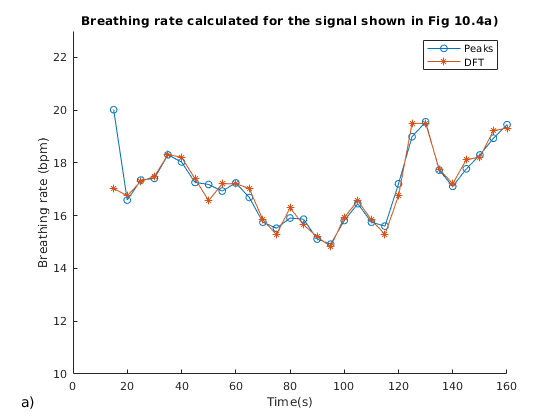

figure
%plot(t,resp_therm)
hold on
plot(t_inst/fs,br_peaks_therm,'-o')
plot(t_inst/fs,br_freq_therm,'-*')
xlabel('Time(s)')
ylabel('Breathing rate (bpm)')
title('Breathing rate calculated for the signal shown in Fig 10.4a)')
legend(['Peaks'],['DFT'])
ylim([10,23])
annonation_save('a)',"Fig9.5a.jpg", SAVE_FLAG);

Plotting breathing rate of FFT-based algorithm

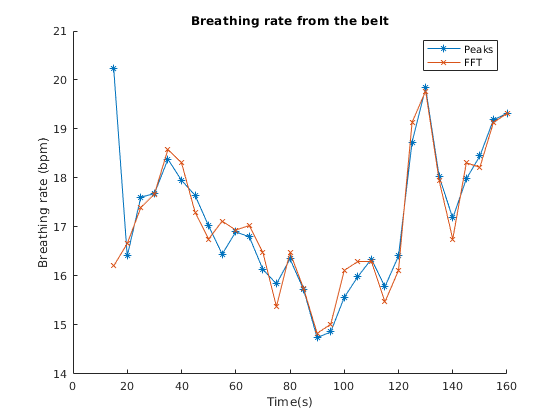

figure
%plot(t,resp_therm)
hold on
plot(t_inst/fs,br_peaks_belt,'-*')
plot(t_inst/fs,br_freq_belt,'-x')
xlabel('Time(s)')
ylabel('Breathing rate (bpm)')
title('Breathing rate from the belt')
legend(['Peaks'],['FFT'])

Show some intermediate processing results

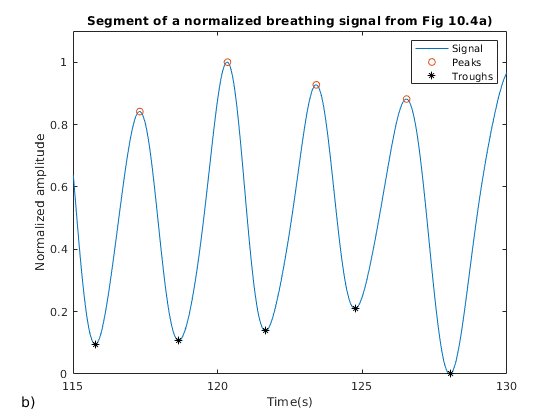

j=24;
sig=resp_therm_f(Segment_ofset(j):Segment_ofset(j)+Segment_length-1);
[m1,j1]=findpeaks(rescale1(sig), 'MinPeakProminence',0.1,'MinPeakDistance',floor(fs/0.6), 'MinPeakWidth', floor(fs/2));
[m2,j2]=findpeaks(-rescale1(sig), 'MinPeakProminence',0.1,'MinPeakDistance',floor(fs/0.6), 'MinPeakWidth', floor(fs/2));
figure
plot(t(Segment_ofset(j):Segment_ofset(j)+Segment_length-1),rescale1(sig))
hold on
plot((Segment_ofset(j)+j1)/fs,m1,'o')
plot((Segment_ofset(j)+j2)/fs,-m2,'k*')
xlabel('Time(s)')
ylabel('Normalized amplitude')
title('Segment of a normalized breathing signal from Fig 10.4a)')
legend(['Signal'],['Peaks'],['Troughs'])
ylim([0,1.1])
annonation_save('b)',"Fig9.5b.jpg", SAVE_FLAG);

Breathing rate is determined by the mean time difference of minimums and maximums.

br_rate_est(sig,fs)

ans = 19.5572

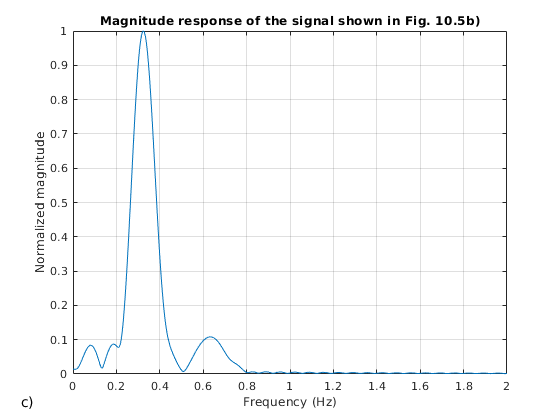


figure
br_freq_therm(j)= br_rate_est_freq(resp_therm_f(Segment_ofset(j):Segment_ofset(j)+Segment_length-1),fs,2,1);

title('Magnitude response of the signal shown in Fig. 10.5b)')
annonation_save('c)',"Fig9.5c.jpg", SAVE_FLAG);

The maximum is at 0.3265 Hz that corresponds to 19.6 breaths per minute.

## Exersizes

Excersize 1:  Window size was set to 15 s and  overlap to 10s (No_everlap=5s).  Analyze the effects of the window size (change from 10s to 30s) and the overlap on the accuracy of the breathing rate estimation algorithms based on peak  detection and based on FFT.

Excersize 2: Instead of loading waveform obtained after exercise from the file 'PEX_T1.mat', load the waveform 'Free_T1.mat' that corresponds to the free breathing signal. Compute the breathing rate using both methods. After that, load the waveform from  "Irregular_T1.mat". Compute the breathing rates. Anayze the discrepancy in the estimation results between the peak and FFT based method.

Excersize 3: Modify the code for computing breathing rate based on peaks to use only peaks (but no troughs). How does that affect the  breathing rate estimation?